spectra = importdata ('spectra.csv');
starNames = importdata ('star_names.csv');
lambdaStart = importdata ('lambda_start.csv');
lambdaDelta = importdata ('lambda_delta.csv');

speedOfLight = 299792.458;
lambdaPr = 656.28;

sz_raw = size (spectra, 1);
stars_count = size (starNames, 1);
lambdaEnd = lambdaStart + (sz_raw - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

[sHa, idx] = min (spectra);
lambdaHa = lambda (idx);
z = (lambdaHa / lambdaPr) - 1;
speed = z * speedOfLight;
movaway = starNames (z > 0);

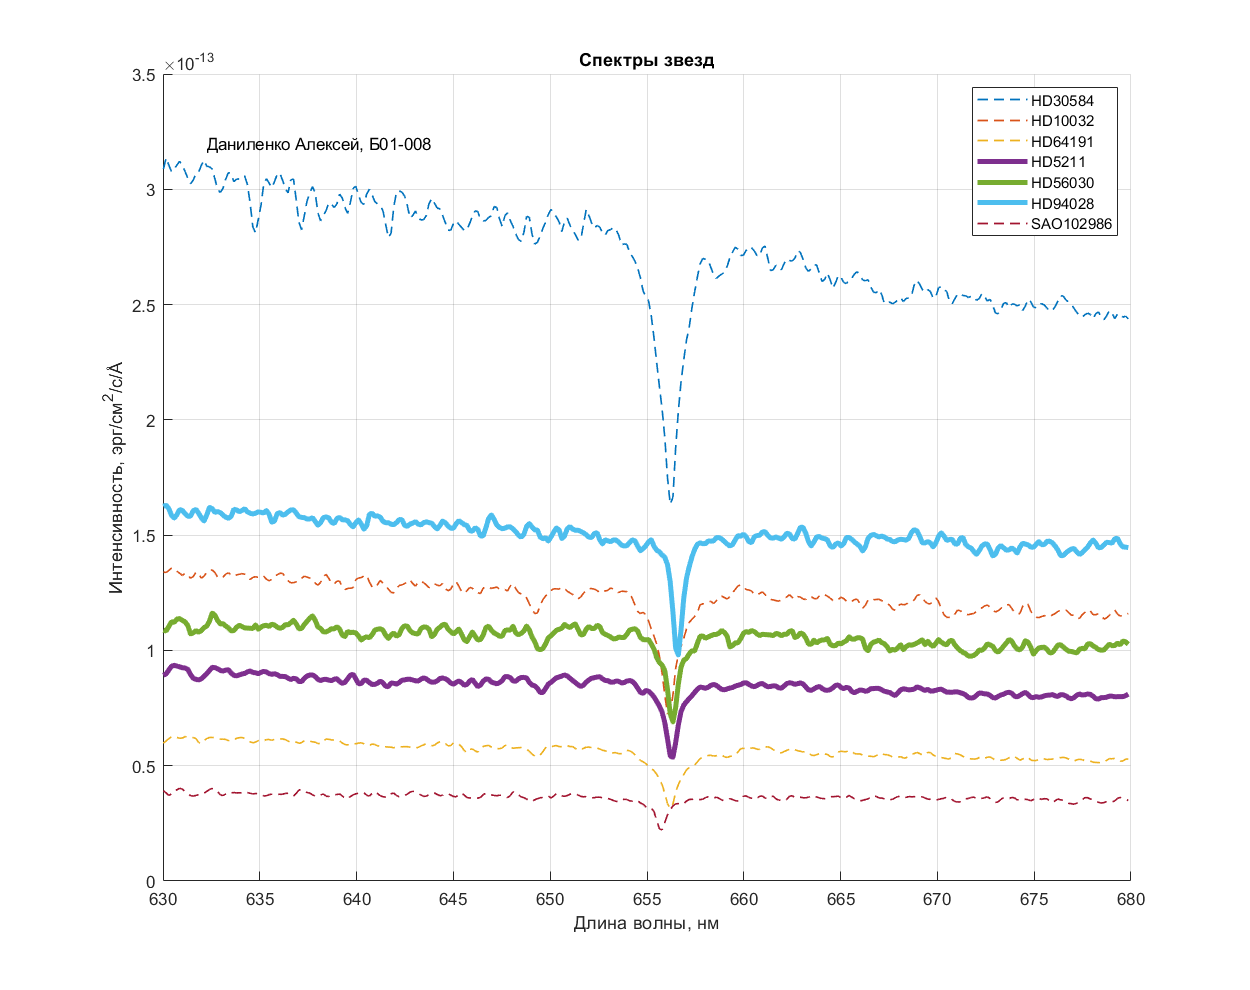

fg = figure;
grid on
set (fg, 'Position', [0, 0, 1000, 1000], 'Visible', 'on');
xlabel ('Длина волны, нм');
ylabel (['Интенсивность, эрг/см^2/c/', char (197)]);
title ('Спектры звезд');
text (lambdaStart + 2, 3.2*10^(-13) , ' Даниленко Алексей, Б01-008');

hold on

for i = 1 : stars_count
    if speed (i) > 0
            plot (lambda, spectra(:, i), 'LineWidth', 3);
    else
            plot (lambda, spectra (:, i), '--', 'LineWidth', 1);
    end
end

legend (starNames);

hold off

saveas (fg, 'spectra.png');